rng('default') % For reproducibility


X = randi(10,8,2)

X =      9     9
    10     3
     6    10
     2     4
     2     2
     3     3
     9     7
     3     5


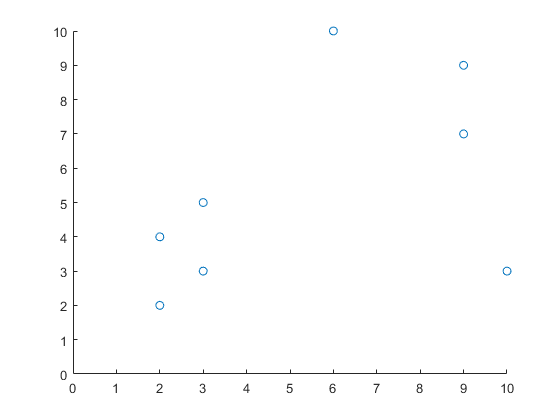

figure;

scatter(X(:,1), X(:,2))
axis([0 10 0 10])


D = pdist(X,"euclidean");
Z = squareform(D)

Z =          0    6.0828    3.1623    8.6023    9.8995    8.4853    2.0000    7.2111
    6.0828         0    8.0623    8.0623    8.0623    7.0000    4.1231    7.2801
    3.1623    8.0623         0    7.2111    8.9443    7.6158    4.2426    5.8310
    8.6023    8.0623    7.2111         0    2.0000    1.4142    7.6158    1.4142
    9.8995    8.0623    8.9443    2.0000         0    1.4142    8.6023    3.1623
    8.4853    7.0000    7.6158    1.4142    1.4142         0    7.2111    2.0000
    2.0000    4.1231    4.2426    7.6158    8.6023    7.2111         0    6.3246
    7.2111    7.2801    5.8310    1.4142    3.1623    2.0000    6.3246         0


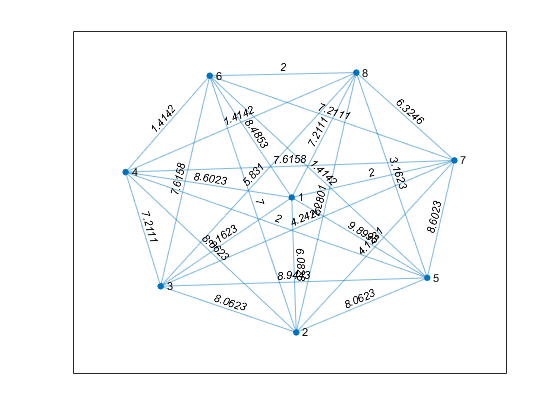

% Z(1,1) = 5
G = graph(Z);
plot(G,'EdgeLabel',G.Edges.Weight)


d = distances(G)

d =          0    6.0828    3.1623    8.6023    9.8995    8.4853    2.0000    7.2111
    6.0828         0    8.0623    8.0623    8.0623    7.0000    4.1231    7.2801
    3.1623    8.0623         0    7.2111    8.9443    7.6158    4.2426    5.8310
    8.6023    8.0623    7.2111         0    2.0000    1.4142    7.6158    1.4142
    9.8995    8.0623    8.9443    2.0000         0    1.4142    8.6023    3.1623
    8.4853    7.0000    7.6158    1.4142    1.4142         0    7.2111    2.0000
    2.0000    4.1231    4.2426    7.6158    8.6023    7.2111         0    6.3246
    7.2111    7.2801    5.8310    1.4142    3.1623    2.0000    6.3246         0


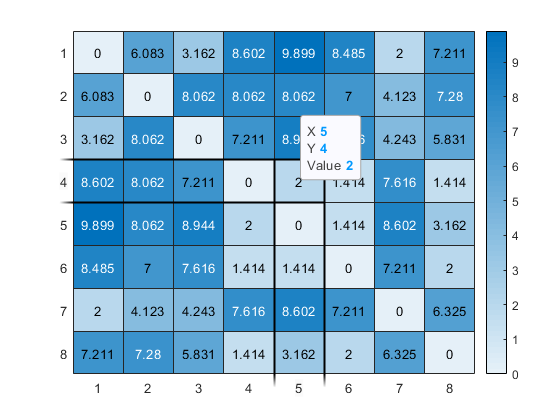

ans =   HeatmapChart with properties:

        XData: {8×1 cell}
        YData: {8×1 cell}
    ColorData: [8×8 double]

  Show all properties


heatmap(d)

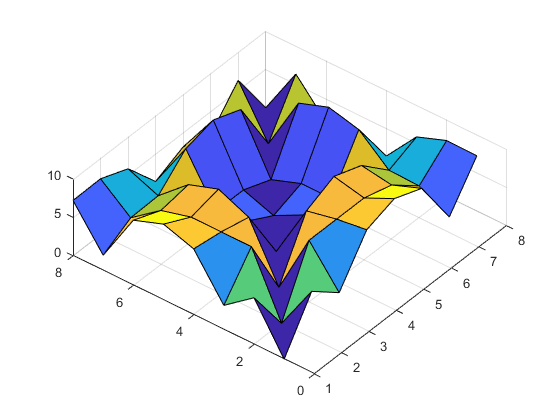

surf(d)


stupid = sum(diag(d,1))

stupid =      0    20



sz= size(Z)

sz =     20    20


Bgy =100;
MORDOR=[]


MORDOR =

     []




DAD = d+Bgy*eye(sz(1));

% [M,I] = min(DAD,[],'all','linear')
% [row,col] = ind2sub(sz,I)
% ORDOR = [col row]
% 
% DAD(col,:) = Bgy;
% DAD(:,col) = Bgy;
% 
% distas(1)=M;

sz= size(Z)

sz =     20    20


Bgy =ceil(max(Z,[],'all'))+1;
MORDOR=[]


MORDOR =

     []




DAD = d+Bgy*eye(sz(1));

for r = 1:sz(1)
    
    DAD = d+Bgy*eye(sz(1));
    row = r
    ORDOR = r;
for j=1:sz(1)-1
[M,col] = min(DAD(row,:));

distas(r,j)=M;
ORDOR = [ORDOR  col];

DAD(row,:) = Bgy;
DAD(:,row) = Bgy;
row=col;
end

MORDOR = [MORDOR ; ORDOR];
end

row = 1

row = 2

row = 3

row = 4

row = 5

row = 6

row = 7

row = 8

row = 9

row = 10

row = 11

row = 12

row = 13

row = 14

row = 15

row = 16

row = 17

row = 18

row = 19

row = 20


[~,bread] = min(sum(distas,2))

bread = 1

optima = MORDOR(bread,:)'

optima =      1
     2
     1
     1
     1
     1
     1
     1
     1
     1


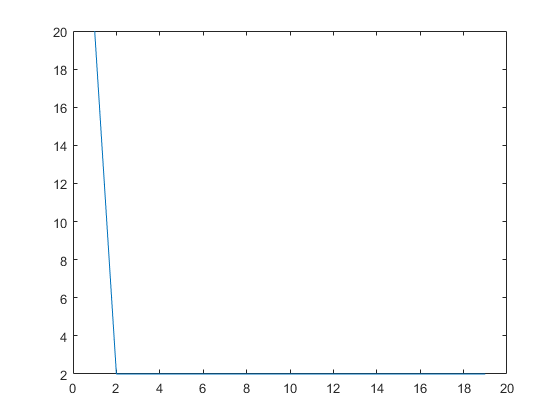


plot(distas(2,:))

[optima] = findorder(Z)

optima =      1
    10
    19
     5
    17
    15
     3
     6
     7
    14



Xoptim = X(MORDOR(bread,:)',:)

Reference to a cleared variable X.

Doptim = pdist(Xoptim,"euclidean");
Zoptim = squareform(Doptim)

surf(Zoptim)